# Flash Responses Measured in Voltage Clamp

ups = grabFromFilter('UP Cells');
downs = grabFromFilter('DOWN Cells');

flashResponseTotalTime = 3; %s
SR_avg = 1000; %hz
avgFlash_Ex_Ups = zeros(0, flashResponseTotalTime * SR_avg);
avgFlash_Inh_Ups = zeros(0, flashResponseTotalTime * SR_avg);
avgFlash_Ex_Downs = zeros(0, flashResponseTotalTime * SR_avg);
avgFlash_Inh_Downs = zeros(0, flashResponseTotalTime * SR_avg);

peakFlash_Ex_Ups = [];
peakFlash_Inh_Ups = [];
peakFlash_Ex_Downs = [];
peakFlash_Inh_Downs = [];

OffPeak_Ex_Ups = [];
OffPeak_Ex_Downs = [];
OffPeak_Inh_Ups = [];
OffPeak_Inh_Downs = [];

chargeFlash_Ex_Ups = [];
chargeFlash_Inh_Ups = [];
chargeFlash_Ex_Downs = [];
chargeFlash_Inh_Downs = [];

%choose which protocols to look at
priorityOrder_1 = {'Flash'}; %first field name should be one of these. Priority is in given order
priorityOrder_2 = {'_ff'; 'Intracellular'}; %child field name should be one of these. Priority is in given order
mustHave_1 = [];
mustHave_2 = {'Intracellular', 'Excitation'};
mustHave_2b = {'Inhibition'};
cantHave_1 = [];
cantHave_2 = {'Extracellular', 'CurrentClamp'}; %avoid anything with these tags
rigMandates = []; %

ttp_Ex_Ups = [];
ttp_Ex_Downs = [];

upCoords = zeros(0, 2);
downCoords = zeros(0, 2);
%ups first
for i = 1:size(ups, 1)
    struct_i = ups{i, 2};
    
    [loc_excitation, pass] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2, cantHave_2, rigMandates);
    if ~pass && loc_excitation.Analysis_Results.totalTime ~= 3000
        pass = 1;
    end
    if ~pass
        %disp(struct_i.cellID)
        avgFlash_Ex_Ups(end+1, :) = loc_excitation.Analysis_Results.meanTrace.meanTrace;
        peakFlash_Ex_Ups = [peakFlash_Ex_Ups; mean(loc_excitation.Analysis_Results.ON_maxNegativePeakByEpoch)];
        chargeFlash_Ex_Ups = [chargeFlash_Ex_Ups; mean(loc_excitation.Analysis_Results.totalChargeByEpoch)];
        ttp_Ex_Ups = [ttp_Ex_Ups; mean(loc_excitation.Analysis_Results.ON_maxNegativePeakByEpoch_timesToPeak)];
        OffPeak_Ex_Ups = [OffPeak_Ex_Ups; mean(loc_excitation.Analysis_Results.OFF_maxNegativePeakByEpoch)];
        upCoords(end+1, :) = struct_i.coordinates.polar;
    end
    
    [loc_inhibition, pass] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2b, cantHave_2, rigMandates);
    if ~pass && loc_inhibition.Analysis_Results.totalTime ~= 3000
        pass = 1;
    end
    if ~pass
        avgFlash_Inh_Ups(end+1, :) = loc_inhibition.Analysis_Results.meanTrace.meanTrace;
        peakFlash_Inh_Ups = [peakFlash_Inh_Ups; mean(loc_inhibition.Analysis_Results.ON_maxPositivePeakByEpoch)];
        chargeFlash_Inh_Ups = [chargeFlash_Inh_Ups; mean(loc_inhibition.Analysis_Results.totalChargeByEpoch)];
        OffPeak_Inh_Ups = [OffPeak_Inh_Ups; mean(loc_inhibition.Analysis_Results.OFF_maxPositivePeakByEpoch)];
    end
    
end
for i = 1:size(downs, 1)
    struct_i = downs{i, 2};
    
    [loc_excitation, pass] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2, cantHave_2, rigMandates);
    if ~pass&& loc_excitation.Analysis_Results.totalTime ~= 3000
        pass = 1;
    end
    if ~pass
        %disp(struct_i.cellID)
        avgFlash_Ex_Downs(end+1, :) = loc_excitation.Analysis_Results.meanTrace.meanTrace;
        peakFlash_Ex_Downs = [peakFlash_Ex_Downs; mean(loc_excitation.Analysis_Results.ON_maxNegativePeakByEpoch)];
        chargeFlash_Ex_Downs = [chargeFlash_Ex_Downs; mean(loc_excitation.Analysis_Results.totalChargeByEpoch)];
        ttp_Ex_Downs = [ttp_Ex_Downs; mean(loc_excitation.Analysis_Results.ON_maxNegativePeakByEpoch_timesToPeak)];
        OffPeak_Ex_Downs = [OffPeak_Ex_Downs; mean(loc_excitation.Analysis_Results.OFF_maxNegativePeakByEpoch)];
        try
        downCoords(end+1, :) = struct_i.coordinates.polar;
        catch
        end
    end
    
    [loc_inhibition, pass] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2b, cantHave_2, rigMandates);
    if ~pass && loc_inhibition.Analysis_Results.totalTime ~= 3000
        pass = 1;
    end
    if ~pass
        avgFlash_Inh_Downs(end+1, :) = loc_inhibition.Analysis_Results.meanTrace.meanTrace;
        peakFlash_Inh_Downs = [peakFlash_Inh_Downs; mean(loc_inhibition.Analysis_Results.ON_maxPositivePeakByEpoch)];
        chargeFlash_Inh_Downs = [chargeFlash_Inh_Downs; mean(loc_inhibition.Analysis_Results.totalChargeByEpoch)];
        OffPeak_Inh_Downs = [OffPeak_Inh_Downs; mean(loc_inhibition.Analysis_Results.OFF_maxPositivePeakByEpoch)];
    end
    
end

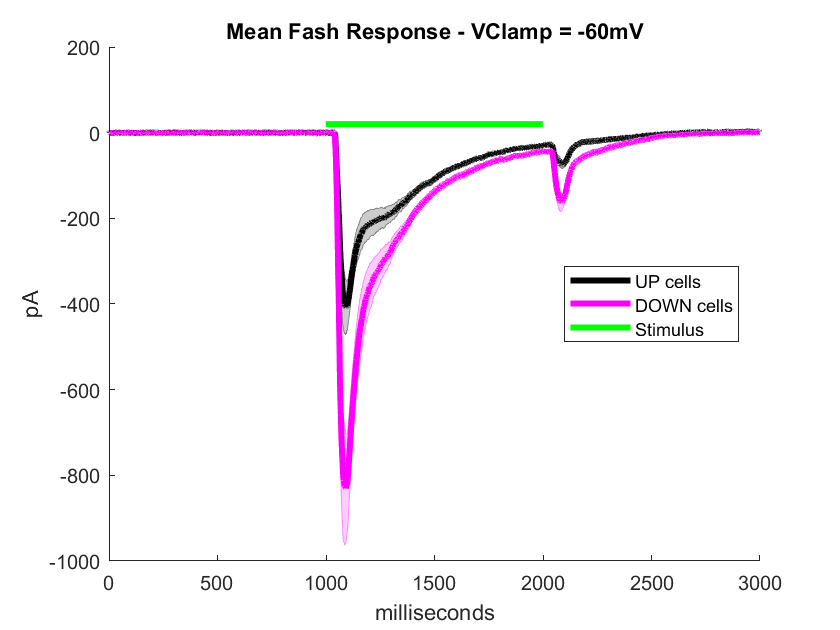

mean_Ex_Ups = mean(avgFlash_Ex_Ups(:, 2:end-1)); %truncate because the low pass filter makes first and last points weird
mean_Ex_Downs = mean(avgFlash_Ex_Downs(:, 2:end-1));
se_Ex_Ups = std(avgFlash_Ex_Ups(:, 2:end-1))/sqrt(size(avgFlash_Ex_Ups, 1));
se_Ex_Downs = std(avgFlash_Ex_Downs(:, 2:end-1))/sqrt(size(avgFlash_Ex_Downs, 1));

mean_Inh_Ups =  mean(avgFlash_Inh_Ups(:, 2:end-1));
mean_Inh_Downs =  mean(avgFlash_Inh_Downs(:, 2:end-1));
se_Inh_Ups = std(avgFlash_Inh_Ups(:, 2:end-1))/sqrt(size(avgFlash_Inh_Ups, 1));
se_Inh_Downs = std(avgFlash_Inh_Downs(:, 2:end-1))/sqrt(size(avgFlash_Inh_Downs, 1));

figure();
title('Mean Fash Response - VClamp = -60mV')
hold on
shadedErrorBar([1:numel(mean_Ex_Ups)], mean_Ex_Ups, se_Ex_Ups, 'lineprops', {'color', [0, 0, 0]/255, 'linewidth', 3})
shadedErrorBar([1:numel(mean_Ex_Downs)], mean_Ex_Downs, se_Ex_Downs, 'lineprops', {'color', [255, 0, 255]/255, 'linewidth', 3})
xlabel('milliseconds')
ylabel('pA')
plot([999, 1999], [20, 20], '-g', 'LineWidth', 3)
l = legend('UP cells', 'DOWN cells', 'Stimulus');
l.Location = 'best';

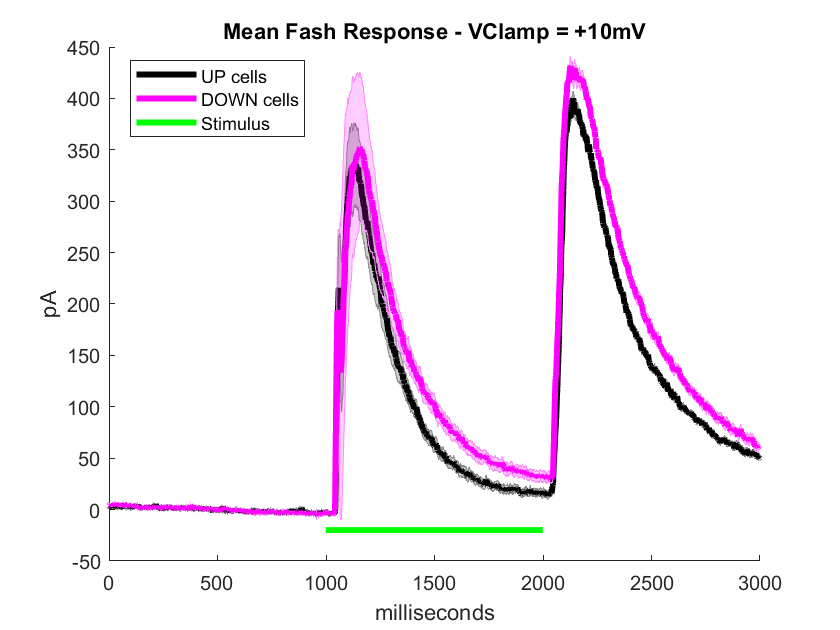


figure();
title('Mean Fash Response - VClamp = +10mV')
hold on
shadedErrorBar([1:numel(mean_Inh_Ups)], mean_Inh_Ups, se_Ex_Ups, 'lineprops', {'color', [0, 0, 0]/255, 'linewidth', 3})
shadedErrorBar([1:numel(mean_Inh_Downs)], mean_Inh_Downs, se_Ex_Downs, 'lineprops', {'color', [255, 0, 255]/255, 'linewidth', 3})
xlabel('milliseconds')
ylabel('pA')
plot([999, 1999], [-20, -20], '-g', 'LineWidth', 3)
l = legend('UP cells', 'DOWN cells', 'Stimulus');
l.Location = 'best';

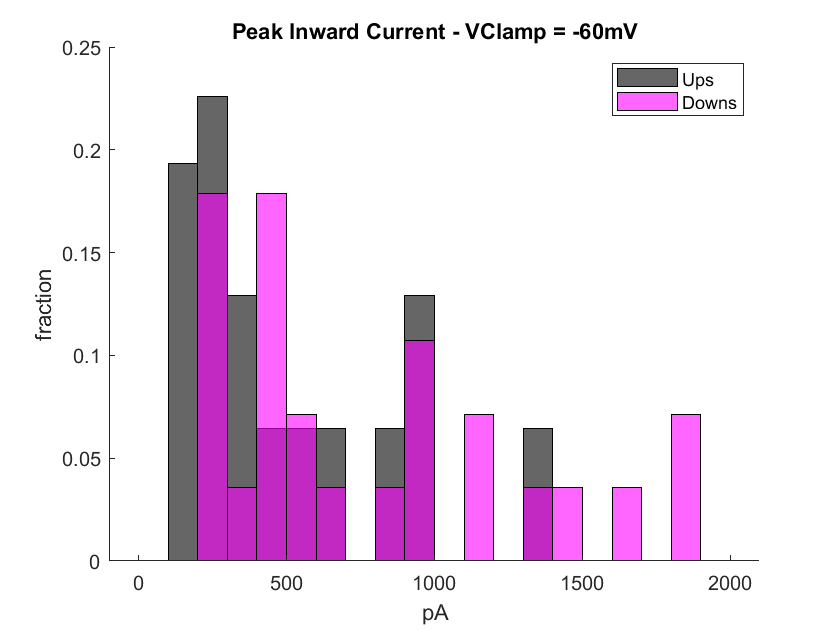


edgs = [0:100:2000];
%histogram of peak ON responses
figure
h1 = histogram(-peakFlash_Ex_Ups, 'BinEdges', edgs, 'FaceColor', 'black', 'Normalization','probability');
hold on
h2 = histogram(-peakFlash_Ex_Downs, 'BinEdges', edgs, 'FaceColor', 'magenta', 'FaceAlpha', 0.6, 'Normalization', 'Probability');
%.BinEdges = h1.BinEdges;
title('Peak Inward Current - VClamp = -60mV')
xlabel('pA')
ylabel('fraction')
legend('Ups', 'Downs')
box off

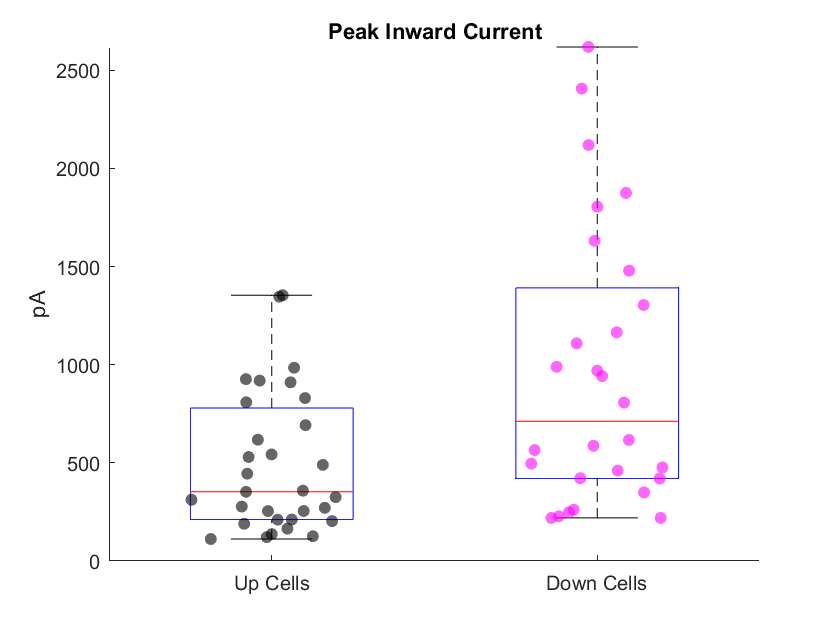

groupIDs = zeros(1, numel([peakFlash_Ex_Ups; peakFlash_Ex_Downs]));
groupIDs(numel(peakFlash_Ex_Ups)+ 1:end) = 1;

allPoints = [-peakFlash_Ex_Ups; -peakFlash_Ex_Downs];

figure
title ('Peak Inward Current')
hold on
boxplot(allPoints, groupIDs, 'Symbol' , '', 'Widths', 0.5)
scatter(ones(1, numel(peakFlash_Ex_Ups)), -peakFlash_Ex_Ups,'filled', 'k', 'MarkerFaceAlpha',0.6, 'XJitter','density', 'XJitterWidth', 0.5)
scatter(ones(1, numel(peakFlash_Ex_Downs))+1, -peakFlash_Ex_Downs,'filled', 'm', 'MarkerFaceAlpha',0.6, 'XJitter','density', 'XJitterWidth', 0.5)
ylim([0 inf])
xticklabels({'Up Cells', 'Down Cells'})
ylabel('pA')
box off


p = ranksum(peakFlash_Ex_Ups, peakFlash_Ex_Downs)

p = 0.0037

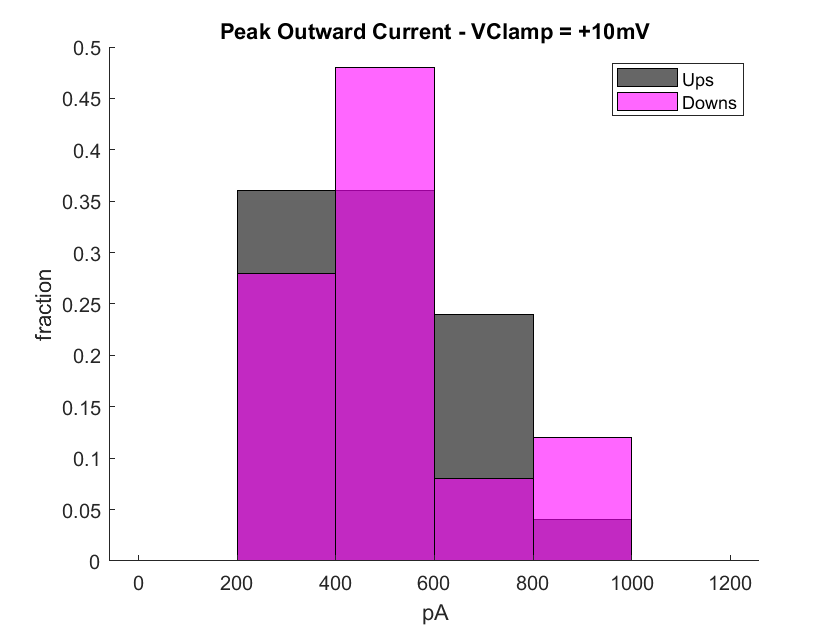

edgs = [0:200:1200];
%histogram of peak ON responses
figure
h1 = histogram(peakFlash_Inh_Ups, 'BinEdges', edgs, 'FaceColor', 'black', 'Normalization','probability');
hold on
h2 = histogram(peakFlash_Inh_Downs,'BinEdges', edgs, 'FaceColor', 'magenta', 'FaceAlpha', 0.6, 'Normalization','probability');
h2.BinEdges = h1.BinEdges;
title('Peak Outward Current - VClamp = +10mV')
xlabel('pA')
ylabel('fraction')
legend('Ups', 'Downs')
box off

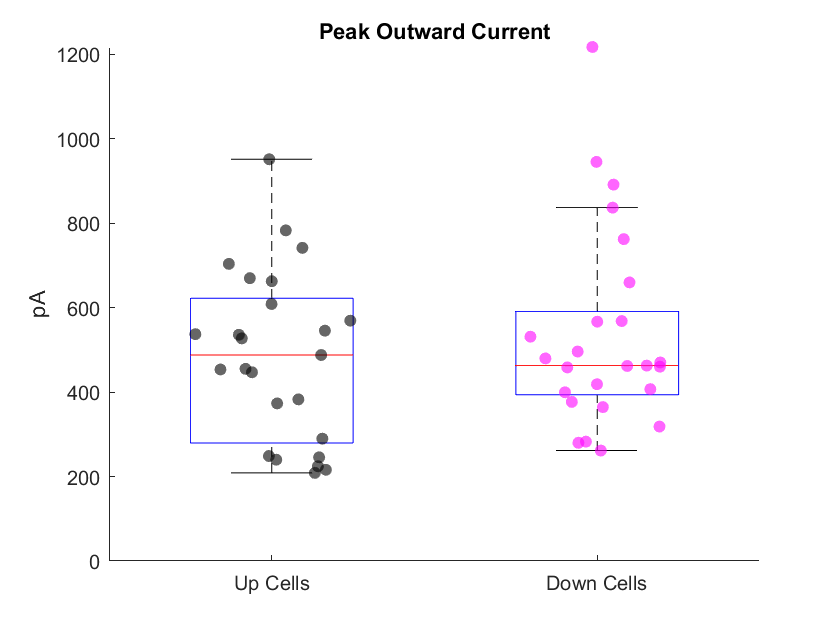

groupIDs = zeros(1, numel([peakFlash_Inh_Ups; peakFlash_Inh_Downs]));
groupIDs(numel(peakFlash_Inh_Ups)+ 1:end) = 1;

allPoints = [peakFlash_Inh_Ups; peakFlash_Inh_Downs];

figure
title ('Peak Outward Current')
hold on
boxplot(allPoints, groupIDs, 'Symbol' , '', 'Widths', 0.5)
scatter(ones(1, numel(peakFlash_Inh_Ups)), peakFlash_Inh_Ups,'filled', 'k', 'MarkerFaceAlpha',0.6, 'XJitter','density', 'XJitterWidth', 0.5)
scatter(ones(1, numel(peakFlash_Inh_Downs))+1, peakFlash_Inh_Downs,'filled', 'm', 'MarkerFaceAlpha',0.6, 'XJitter','density', 'XJitterWidth', 0.5)
ylim([0 inf])
xticklabels({'Up Cells', 'Down Cells'})
ylabel('pA')
box off

p = ranksum(peakFlash_Inh_Ups, peakFlash_Inh_Downs)

p = 0.6139

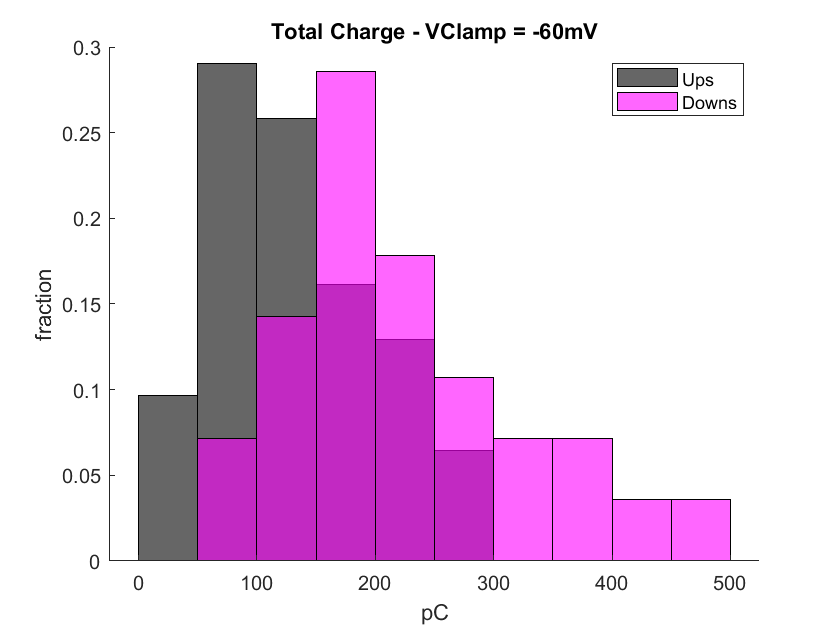

edgs = [0:50:500];
figure
h1 = histogram(-chargeFlash_Ex_Ups, 'BinEdges', edgs, 'FaceColor', 'black', 'Normalization', 'probability');
hold on
h2 = histogram(-chargeFlash_Ex_Downs, 'BinEdges', edgs, 'FaceColor', 'magenta', 'FaceAlpha', 0.6, 'Normalization', 'probability');
title('Total Charge - VClamp = -60mV')
xlabel('pC')
ylabel('fraction')
legend('Ups', 'Downs')
box off

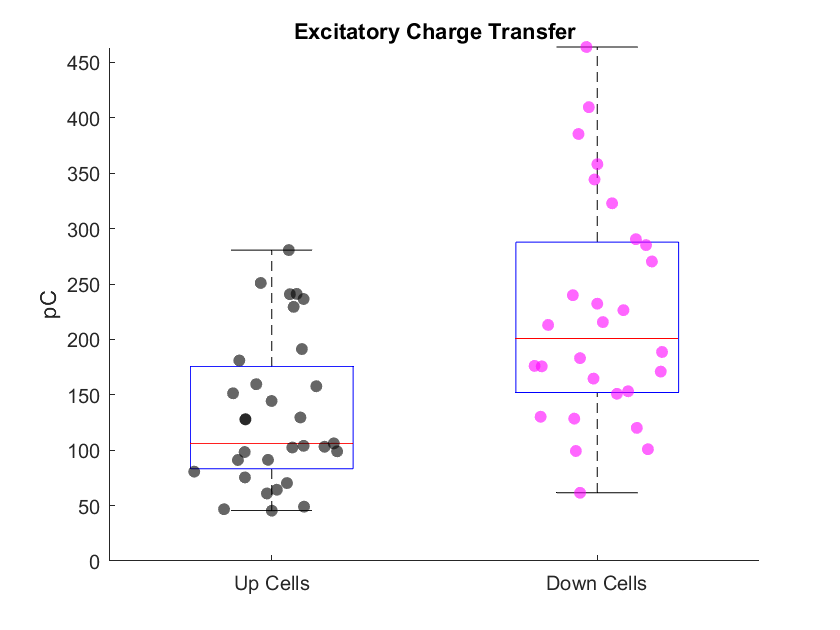

groupIDs = zeros(1, numel([chargeFlash_Ex_Ups; chargeFlash_Ex_Downs]));
groupIDs(numel(chargeFlash_Ex_Ups)+ 1:end) = 1;

allPoints = [-chargeFlash_Ex_Ups; -chargeFlash_Ex_Downs];

figure
title ('Excitatory Charge Transfer')
hold on
boxplot(allPoints, groupIDs, 'Symbol' , '', 'Widths', 0.5)
scatter(ones(1, numel(chargeFlash_Ex_Ups)), -chargeFlash_Ex_Ups,'filled', 'k', 'MarkerFaceAlpha',0.6, 'XJitter','density', 'XJitterWidth', 0.5)
scatter(ones(1, numel(chargeFlash_Ex_Downs))+1, -chargeFlash_Ex_Downs,'filled', 'm', 'MarkerFaceAlpha',0.6, 'XJitter','density', 'XJitterWidth', 0.5)
ylim([0 inf])
xticklabels({'Up Cells', 'Down Cells'})
ylabel('pC')
box off

p = ranksum(chargeFlash_Ex_Ups, chargeFlash_Ex_Downs)

p = 3.9352e-04

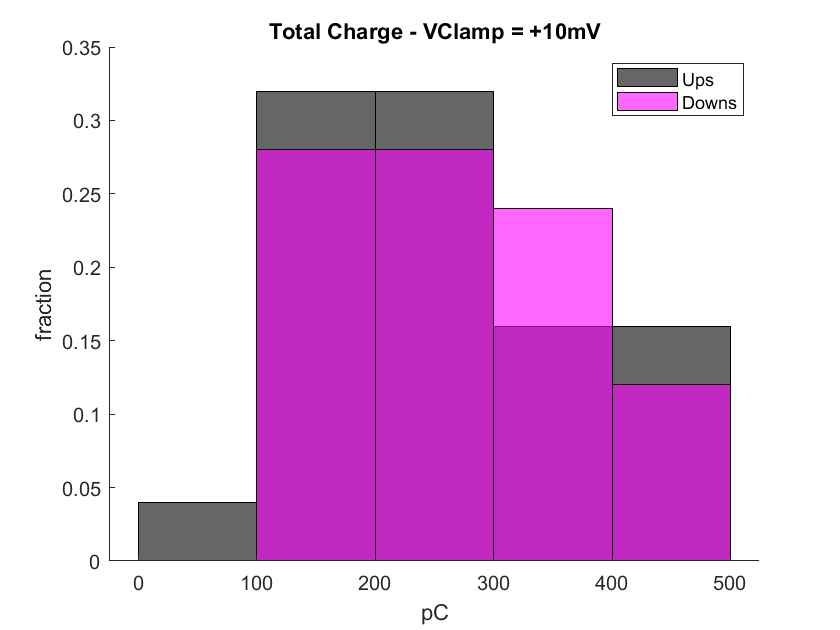

figure
h1 = histogram(chargeFlash_Inh_Ups, 'FaceColor', 'black', 'Normalization','probability');
hold on
h2 = histogram(chargeFlash_Inh_Downs, 'FaceColor', 'magenta', 'FaceAlpha', 0.6, 'Normalization','probability');
h2.BinEdges = h1.BinEdges;
title('Total Charge - VClamp = +10mV')
xlabel('pC')
ylabel('fraction')
legend('Ups', 'Downs')
box off

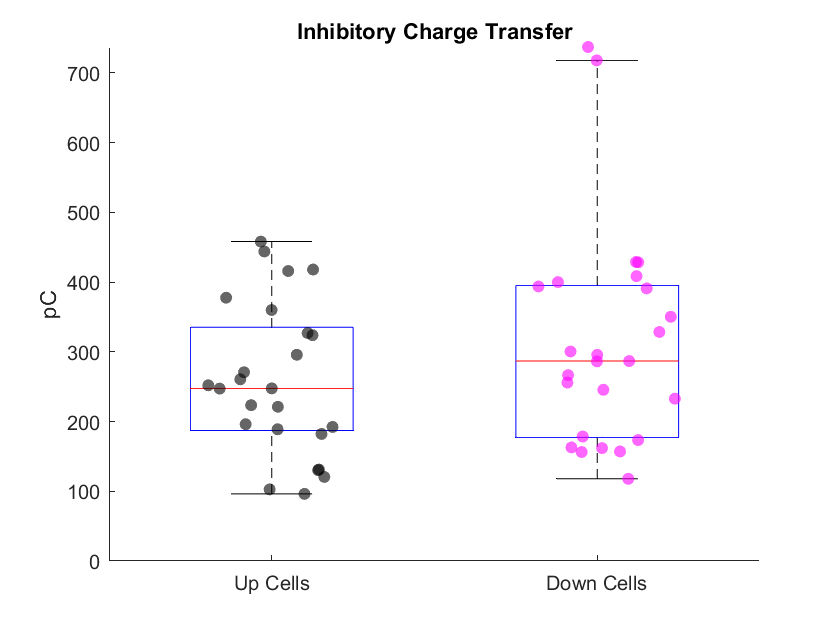

groupIDs = zeros(1, numel([chargeFlash_Inh_Ups; chargeFlash_Inh_Downs]));
groupIDs(numel(chargeFlash_Inh_Ups)+ 1:end) = 1;

allPoints = [chargeFlash_Inh_Ups; chargeFlash_Inh_Downs];

figure
title ('Inhibitory Charge Transfer')
hold on
boxplot(allPoints, groupIDs, 'Symbol' , '', 'Widths', 0.5)
scatter(ones(1, numel(chargeFlash_Inh_Ups)), chargeFlash_Inh_Ups,'filled', 'k', 'MarkerFaceAlpha',0.6, 'XJitter','density', 'XJitterWidth', 0.5)
scatter(ones(1, numel(chargeFlash_Inh_Downs))+1, chargeFlash_Inh_Downs,'filled', 'm', 'MarkerFaceAlpha',0.6, 'XJitter','density', 'XJitterWidth', 0.5)
ylim([0 inf])
xticklabels({'Up Cells', 'Down Cells'})
ylabel('pC')
box off


p = ranksum(chargeFlash_Inh_Ups, chargeFlash_Inh_Downs)

p = 0.3038

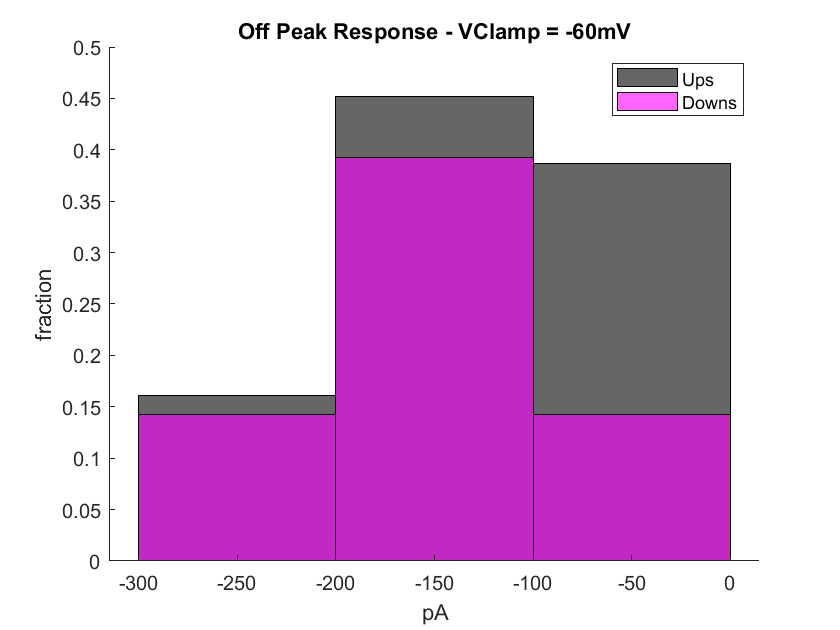

%histogram of peak ON responses
figure
h1 = histogram(OffPeak_Ex_Ups, 'FaceColor', 'black', 'Normalization','probability');
hold on
h2 = histogram(OffPeak_Ex_Downs, 'FaceColor', 'magenta', 'FaceAlpha', 0.6, 'Normalization', 'probability');
h2.BinEdges = h1.BinEdges;
title('Off Peak Response - VClamp = -60mV')
xlabel('pA')
ylabel('fraction')
legend('Ups', 'Downs')
box off

p = ranksum(OffPeak_Ex_Ups, OffPeak_Ex_Downs)

p = 1.8276e-04

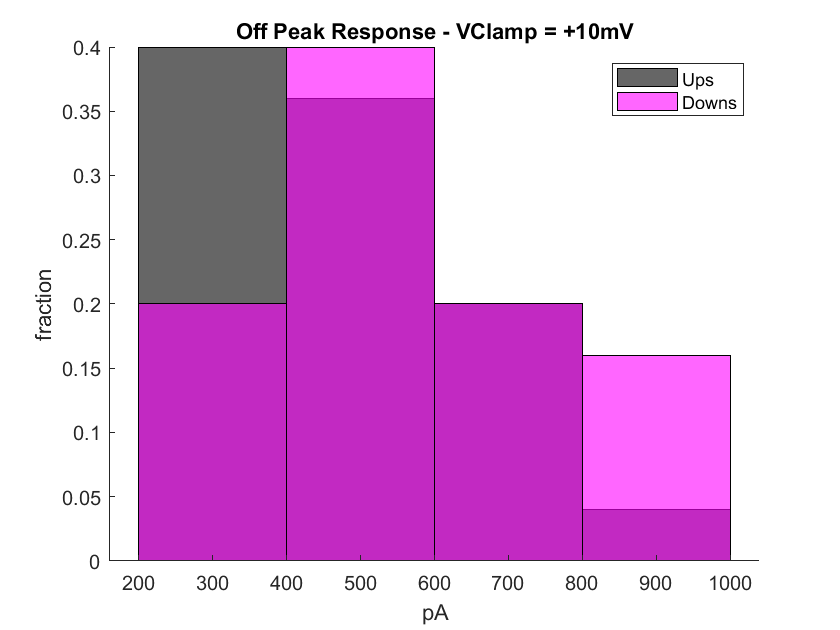

%histogram of peak OFF responses
figure
h1 = histogram(OffPeak_Inh_Ups, 'FaceColor', 'black', 'Normalization', 'probability');
hold on
h2 = histogram(OffPeak_Inh_Downs, 'FaceColor', 'magenta', 'FaceAlpha', 0.6, 'Normalization', 'probability');
h2.BinEdges = h1.BinEdges;
title('Off Peak Response - VClamp = +10mV')
xlabel('pA')
ylabel('fraction')
legend('Ups', 'Downs')
box off

p = ranksum(OffPeak_Inh_Ups, OffPeak_Inh_Downs)

p = 0.3618

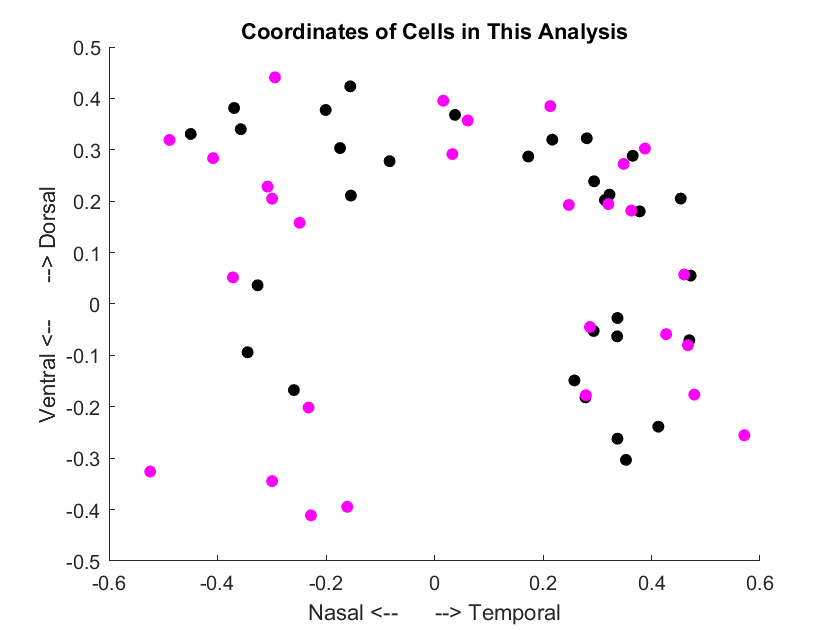

[xUp,yUp] = pol2cart(upCoords(:, 1), upCoords(:, 2));
[xDown,yDown] = pol2cart(downCoords(:, 1), downCoords(:, 2));

figure
title('Coordinates of Cells in This Analysis')
hold on
scatter(-xUp, yUp, 'k', 'filled')
scatter(-xDown, yDown, 'm', 'filled')
xlabel('Nasal <--      --> Temporal')
ylabel('Ventral <--      --> Dorsal')